# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 21-Nov-2021 13:03:00

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([76 150 3],"Name","imageinput_1")
    convolution2dLayer([3 3],64,"Name","conv_1_1","Padding",[1 1 1 1])
    reluLayer("Name","relu_1_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([76 150 1],"Name","imageinput_2")
    convolution2dLayer([3 3],64,"Name","conv_1_2","Padding",[1 1 1 1])
    reluLayer("Name","relu_1_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv_2_1","Padding",[1 1 1 1])
    reluLayer("Name","relu_2_1")
    transposedConv2dLayer([4 4],64,"Name","transposed-conv_1","Cropping",[1 1 1 1],"Stride",[2 2])
    convolution2dLayer([1 1],2,"Name","conv_3_1")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv_2_2","Padding",[1 1 1 1])
    reluLayer("Name","relu_2_2")
    transposedConv2dLayer([4 4],64,"Name","transposed-conv_2","Cropping",[1 1 1 1],"Stride",[2 2])
    convolution2dLayer([1 1],2,"Name","conv_3_2")
    softmaxLayer("Name","softmax")
    pixelClassificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

layer = focalLossLayer("Name","focalloss");
%lgraph = replaceLayer(lgraph,"classoutput",layer);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"relu_1_1","addition/in2");
lgraph = connectLayers(lgraph,"relu_1_2","addition/in1");

## Plot Layers

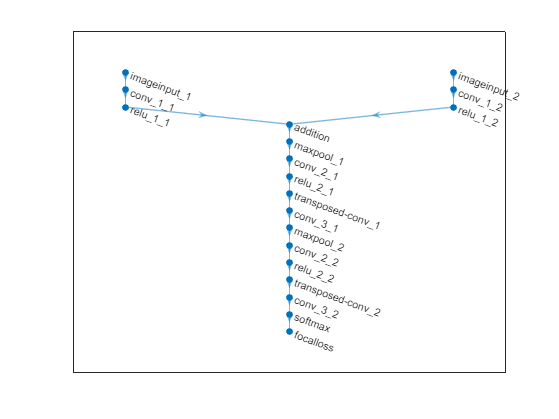


%analyzeNetwork(lgraph);

%plot(lgraph);